% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 36);

% Specify sheet and range
opts.Sheet = "Planilha1";
opts.DataRange = "A41:AJ10981";

% Specify column names and types
opts.VariableNames = ["ScanSweepTime_Sec_", "ScanNumber", "x101Time_Sec_", "x101__C_", "x102Time_Sec_", "x102__C_", "x103Time_Sec_", "x103__C_", "x104Time_Sec_", "x104__C_", "x105Time_Sec_", "x105__C_", "x106Time_Sec_", "x106__C_", "x107Time_Sec_", "x107__C_", "x108Time_Sec_", "x108__C_", "x109Time_Sec_", "x109__C_", "x110Time_Sec_", "x110__C_", "x111Time_Sec_", "x111__C_", "x112Time_Sec_", "x112__C_", "x113Time_Sec_", "x113__C_", "x114Time_Sec_", "x114__C_", "x115Time_Sec_", "x115__C_", "x116Time_Sec_", "x116__C_", "x117Time_Sec_", "x117_Vac_"];
opts.VariableTypes = ["datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double"];

% Import the data
data2 = readtimetable("C:\Users\PEDRO\OneDrive\Documentos\Insper\2024.2\TransCal\Projeto 1\TransCal_Projeto1\data.xlsx", opts, "UseExcel", false, "RowTimes", "ScanSweepTime_Sec_");

% Clear temporary variables
clear opts

% Display results
data2

data2 = 10941×35 timetable
     ScanSweepTime_Sec_     ScanNumber       x101Time_Sec_        x101__C_       x102Time_Sec_        x102__C_       x103Time_Sec_        x103__C_       x104Time_Sec_        x104__C_       x105Time_Sec_        x105__C_       x106Time_Sec_        x106__C_       x107Time_Sec_        x107__C_       x108Time_Sec_        x108__C_       x109Time_Sec_        x109__C_       x110Time_Sec_        x110__C_       x111Time_Sec_        x111__C_       x112Time_Sec_        x112__C_       x113Time_Sec_        x113__C_

% Gráfico 1
time = data.x101Time_Sec_

time = 10941×1 datetime array
   16-Sep-2024 08:32:41
   16-Sep-2024 08:32:51
   16-Sep-2024 08:33:01
   16-Sep-2024 08:33:11
   16-Sep-2024 08:33:21
   16-Sep-2024 08:33:31
   16-Sep-2024 08:33:41
   16-Sep-2024 08:33:51
   16-Sep-2024 08:34:01
   16-Sep-2024 08:34:11
   16-Sep-2024 08:34:21
   16-Sep-2024 08:34:31
   16-Sep-2024 08:34:41
   16-Sep-2024 08:34:51
   16-Sep-2024 08:35:01
   16-Sep-2024 08:35:11
   16-Sep-2024 08:35:21
   16-Sep-2024 08:35:31
   16-Sep-2024 08:35:41
   16-Sep-2024 08:35:51
   16-Sep-2024 08:36:01
   16-Sep-2024 08:36:11
   16-Sep-2024 08:36:21
   16-Sep-2024 08:36:31
   16-Sep-2024 08:36:41
   16-Sep-2024 08:36:51
   16-Sep-2024 08:37:01
   16-Sep-2024 08:37:11
   16-Sep-2024 08:37:21
   16-Sep-2024 08:37:31


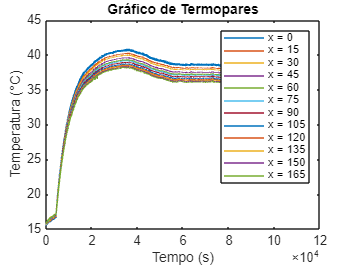

tamanho_time = length(time);
vetor_time = 10 * (0:tamanho_time-1);
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_time, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Tempo (s)');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares');

% Calculando a temperatura média ambiente no intervalo
ind = ~isnan(data.x101__C_);
Tamb_col=data.x101__C_(ind);

Tmamb = mean(Tamb_col);

% Calculando a temperatura média na aleta no intervalo
